## **Metoda **kierunków sprzężonych Hooke'a-Jeevesa

Wyłączenie warningów, format wyświetlania "long", wyczyszczenie wszystkich zmiennych

warning('off','all')
format long
clear all, close all

disp('Przykład 3.7')

Przykład 3.7


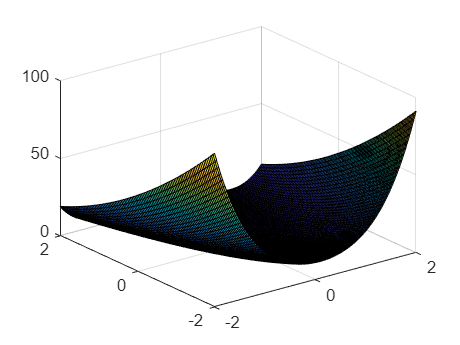

f1 = @(x) 2.5*(x(1).^2-x(2))^2 + (1-x(1))^2;

% graficzne przedstawienie funkcji
t = linspace(-2,2,100);
[xx,yy] = meshgrid(t,t);
surf(xx,yy,arrayfun(@(x,y)f1([x,y]),xx,yy))


P = [-0.5, 1];  % punkt startowy
s = 0.5;  %  długość kroku
alpha = 0.5;  % zmniejszenie kroku po niepowodzeniu
epsilon = 0.01;  % dokładność
N_max = 10000;
%disp('Kolejne punkty bazowe:')
[X, fun] = HookJeeves(f1, P, s, alpha, epsilon, N_max, 1);

Kolejne punkty bazowe:
xB = (0, 0.5)
xB = (0.5, 0)
xB = (0.5, 0.25)
xB = (0.75, 0.5)
xB = (0.75, 0.5625)
xB = (0.8125, 0.6875)
xB = (0.9375, 0.875)
xB = (1, 1)



disp('Oszacowanie minimum funkcji celu:')

Oszacowanie minimum funkcji celu:


disp(['x* = (', num2str(X(1)), ', ', num2str(X(2)), ')']);

x* = (1, 1)


disp('Wartość funkcji w tym punkcie:')

Wartość funkcji w tym punkcie:


disp(['f(x*) = ', num2str(fun)])

f(x*) = 0


disp(' ')

disp('------------------------------------')

------------------------------------


disp('Przykład 3.8')

Przykład 3.8


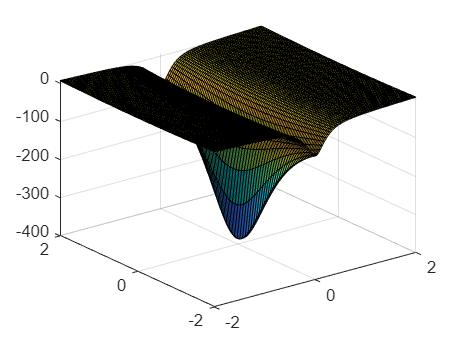

f2 = @(x) x(1).^2 + x(2).^2 - (400/(100*x(1).^2 + x(2).^2 + 1));
P = [0.5, 3];  % punkt startowy
s = 0.5;  %  długość kroku
alpha = 0.5;  % zmniejszenie kroku po niepowodzeniu
epsilon = 0.01;  % dokładność
N_max = 1000;

% graficzne przedstawienie funkcji
t = linspace(-2,2,100);
[xx,yy] = meshgrid(t,t);
surf(xx,yy,arrayfun(@(x,y)f2([x,y]),xx,yy))


[X, fun] = HookJeeves(f2, P, s, alpha, epsilon, N_max, 1);

Kolejne punkty bazowe:
xB = (0, 2.5)
xB = (0, 1.5)
xB = (0, 0)


disp('Oszacowanie minimum funkcji celu:')

Oszacowanie minimum funkcji celu:


disp(['x* = (', num2str(X(1)), ', ', num2str(X(2)), ')']);

x* = (0, 0)


disp('Wartość funkcji w tym punkcie:')

Wartość funkcji w tym punkcie:


disp(['f(x*) = ', num2str(fun)])

f(x*) = -400


% Dane do naszego zadania
s = 0.5;         % długość kroku
alpha = 0.5;     % współczynnik zmniejszania kroku
epsilon = 1e-6;  % dokładność
N_max = 5000;    % maskymalna liczba iteracji

% Funkcja:
f = @(x) x(1)-(4*(x(1)+x(2)).*exp(-x(1).^2 - x(2).^2)+0.1)^2;
% Funkcja *(-1) - do szukania maksimum dla tego samego algorytmu
f_2 = @(x) (-1)*(x(1)-(4*(x(1)+x(2)).*exp(-x(1).^2 - x(2).^2)+0.1)^2);

% Punkty startowe w kolejnych eksperymentach
P1 = [-1, -1];
P2 = [0, 0];
P3 = [3, 3];
P4 = [-0.8, 1];
P5 = [-2, -1];
P6 = [-2, -2];

disp('----------------------------------------------------------')

----------------------------------------------------------


disp('Funkcja z naszego zadania')

Funkcja z naszego zadania


disp('------------------------------------')

------------------------------------


disp(['   Dla punktu startowego (', num2str(P1(1)), ', ', num2str(P1(2)), ')']);

   Dla punktu startowego (-1, -1)


disp("Oszacowanie minimum funkcji celu wynosi:")

Oszacowanie minimum funkcji celu wynosi:


x* = (-0.53345, -0.48902)


Wartość funkcji w tym punkcie:


f(x*) = -5.9275


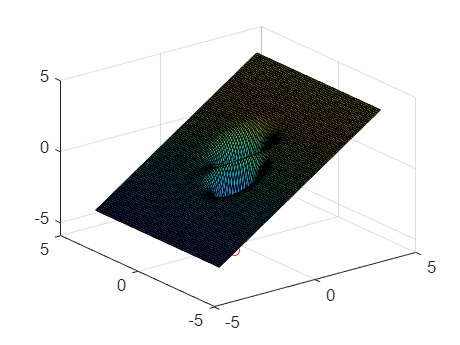

[X, fun, error] = HookJeeves(f, P1, s, alpha, epsilon, N_max, 0);
if error == 0
    
    disp(['x* = (', num2str(X(1)), ', ', num2str(X(2)), ')']);
    disp('Wartość funkcji w tym punkcie:')
    disp(['f(x*) = ', num2str(fun)])
    
    figure
    t = linspace(-4,4,100);
    [xx,yy] = meshgrid(t,t);
    surf(xx,yy,arrayfun(@(x,y)f([x,y]),xx,yy))
    hold on
    scatter3(X(1), X(2), fun, "o", "r")
    hold off
end


disp("Oszacowanie maksimum funkcji celu:")

Oszacowanie maksimum funkcji celu:


[X, fun, error] = HookJeeves(f_2, P1, s, alpha, epsilon, N_max, 0);

Błąd - przekroczono maksymalną ilość iteracji


if error == 0
    disp(['x* = (', num2str(X(1)), ', ', num2str(X(2)), ')']);
    disp('Wartość funkcji w tym punkcie:')
    disp(['f(x*) = ', num2str(-fun)])
    disp(' ')
end

disp('------------------------------------')

------------------------------------


disp(['   Dla punktu startowego (', num2str(P2(1)), ', ', num2str(P2(2)), ')']);

   Dla punktu startowego (0, 0)


disp("Oszacowanie minimum funkcji celu wynosi:")

Oszacowanie minimum funkcji celu wynosi:


x* = (0.46943, 0.51033)


Wartość funkcji w tym punkcie:


f(x*) = -5.8966


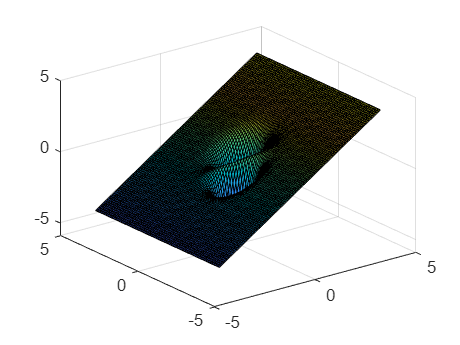

[X, fun, error] = HookJeeves(f, P2, s, alpha, epsilon, N_max, 0);
if error == 0
    
    disp(['x* = (', num2str(X(1)), ', ', num2str(X(2)), ')']);
    disp('Wartość funkcji w tym punkcie:')
    disp(['f(x*) = ', num2str(fun)])
    
    figure
    t = linspace(-4,4,100);
    [xx,yy] = meshgrid(t,t);
    surf(xx,yy,arrayfun(@(x,y)f([x,y]),xx,yy))
    hold on
    scatter3(X(1), X(2), fun, "o", "r")
    hold off
end


disp("Oszacowanie maksimum funkcji celu:")

Oszacowanie maksimum funkcji celu:


[X, fun, error] = HookJeeves(f_2, P2, s, alpha, epsilon, N_max, 0);

Błąd - przekroczono maksymalną ilość iteracji


if error == 0
    disp(['x* = (', num2str(X(1)), ', ', num2str(X(2)), ')']);
    disp('Wartość funkcji w tym punkcie:')
    disp(['f(x*) = ', num2str(-fun)])
    disp(' ')
end

disp('------------------------------------')

------------------------------------


disp(['   Dla punktu startowego (', num2str(P3(1)), ', ', num2str(P3(2)), ')']);

   Dla punktu startowego (3, 3)


disp("Oszacowanie minimum funkcji celu wynosi:")

Oszacowanie minimum funkcji celu wynosi:


x* = (-0.53345, -0.48902)


Wartość funkcji w tym punkcie:


f(x*) = -5.9275


[X, fun, error] = HookJeeves(f, P3, s, alpha, epsilon, N_max, 0);
if error == 0
    
    disp(['x* = (', num2str(X(1)), ', ', num2str(X(2)), ')']);
    disp('Wartość funkcji w tym punkcie:')
    disp(['f(x*) = ', num2str(fun)])
    
    figure
    t = linspace(-4,4,100);
    [xx,yy] = meshgrid(t,t);
    surf(xx,yy,arrayfun(@(x,y)f([x,y]),xx,yy))
    hold on
    scatter3(X(1), X(2), fun, "o", "r")
    hold off
end


disp("Oszacowanie maksimum funkcji celu:")

Oszacowanie maksimum funkcji celu:


[X, fun, error] = HookJeeves(f_2, P3, s, alpha, epsilon, N_max, 0);

Błąd - przekroczono maksymalną ilość iteracji


if error == 0
    disp(['x* = (', num2str(X(1)), ', ', num2str(X(2)), ')']);
    disp('Wartość funkcji w tym punkcie:')
    disp(['f(x*) = ', num2str(-fun)])
    disp(' ')
end

disp('------------------------------------')

------------------------------------


disp(['   Dla punktu startowego (', num2str(P4(1)), ', ', num2str(P4(2)), ')']);

   Dla punktu startowego (-0.8, 1)


disp("Oszacowanie minimum funkcji celu wynosi:")

Oszacowanie minimum funkcji celu wynosi:


x* = (0.46944, 0.51033)


Wartość funkcji w tym punkcie:


f(x*) = -5.8966


[X, fun, error] = HookJeeves(f, P4, s, alpha, epsilon, N_max, 0);
if error == 0
    
    disp(['x* = (', num2str(X(1)), ', ', num2str(X(2)), ')']);
    disp('Wartość funkcji w tym punkcie:')
    disp(['f(x*) = ', num2str(fun)])
    
    figure
    t = linspace(-4,4,100);
    [xx,yy] = meshgrid(t,t);
    surf(xx,yy,arrayfun(@(x,y)f([x,y]),xx,yy))
    hold on
    scatter3(X(1), X(2), fun, "o", "r")
    hold off
end


disp("Oszacowanie maksimum funkcji celu:")

Oszacowanie maksimum funkcji celu:


[X, fun, error] = HookJeeves(f_2, P4, s, alpha, epsilon, N_max, 0);

Błąd - przekroczono maksymalną ilość iteracji


if error == 0
    disp(['x* = (', num2str(X(1)), ', ', num2str(X(2)), ')']);
    disp('Wartość funkcji w tym punkcie:')
    disp(['f(x*) = ', num2str(-fun)])
    disp(' ')
end

disp('------------------------------------')

------------------------------------


disp(['   Dla punktu startowego (', num2str(P5(1)), ', ', num2str(P5(2)), ')']);

   Dla punktu startowego (-2, -1)


disp("Oszacowanie minimum funkcji celu wynosi:")

Oszacowanie minimum funkcji celu wynosi:


[X, fun, error] = HookJeeves(f, P5, s, alpha, epsilon, N_max, 0);

Błąd - przekroczono maksymalną ilość iteracji


if error == 0
    
    disp(['x* = (', num2str(X(1)), ', ', num2str(X(2)), ')']);
    disp('Wartość funkcji w tym punkcie:')
    disp(['f(x*) = ', num2str(fun)])
    
    figure
    t = linspace(-4,4,100);
    [xx,yy] = meshgrid(t,t);
    surf(xx,yy,arrayfun(@(x,y)f([x,y]),xx,yy))
    hold on
    scatter3(X(1), X(2), fun, "o", "r")
    hold off
end

disp("Oszacowanie maksimum funkcji celu:")

Oszacowanie maksimum funkcji celu:


[X, fun, error] = HookJeeves(f_2, P5, s, alpha, epsilon, N_max, 0);

Błąd - przekroczono maksymalną ilość iteracji


if error == 0
    disp(['x* = (', num2str(X(1)), ', ', num2str(X(2)), ')']);
    disp('Wartość funkcji w tym punkcie:')
    disp(['f(x*) = ', num2str(-fun)])
    disp(' ')
end

disp('------------------------------------')

------------------------------------


disp(['   Dla punktu startowego (', num2str(P6(1)), ', ', num2str(P6(2)), ')']);

   Dla punktu startowego (-2, -2)


disp("Oszacowanie minimum funkcji celu wynosi:")

Oszacowanie minimum funkcji celu wynosi:


[X, fun, error] = HookJeeves(f, P6, s, alpha, epsilon, N_max, 0);

Błąd - przekroczono maksymalną ilość iteracji


if error == 0
    
    disp(['x* = (', num2str(X(1)), ', ', num2str(X(2)), ')']);
    disp('Wartość funkcji w tym punkcie:')
    disp(['f(x*) = ', num2str(fun)])
    
    figure
    t = linspace(-4,4,100);
    [xx,yy] = meshgrid(t,t);
    surf(xx,yy,arrayfun(@(x,y)f([x,y]),xx,yy))
    hold on
    scatter3(X(1), X(2), fun, "o", "r")
    hold off
end

disp("Oszacowanie maksimum funkcji celu:")

Oszacowanie maksimum funkcji celu:


[X, fun, error] = HookJeeves(f_2, P6, s, alpha, epsilon, N_max, 0);

Błąd - przekroczono maksymalną ilość iteracji


if error == 0
    disp(['x* = (', num2str(X(1)), ', ', num2str(X(2)), ')']);
    disp('Wartość funkcji w tym punkcie:')
    disp(['f(x*) = ', num2str(-fun)])
    disp(' ')
end

function [x_min, fun, err] = HookJeeves(f, x, s, alpha, epsilon, N_max, disp_xB)
    i = 1;
    err = 0;
    % możliwość śledzenia kolejnych punktów bazowych
    if disp_xB == 1
        disp('Kolejne punkty bazowe:')
    end
    while s >= epsilon
        if i >= N_max
            break
        end
        xB = x;
        x = probuj(f, xB, s);
        if f(x) < f(xB)
            while f(x) < f(xB)
                if i >= N_max
                    err = 1;
                    disp("Błąd - przekroczono maksymalną ilość iteracji")
                    break
                end
                x_B = xB;   % x_B - stara baza
                xB = x;     % xB - aktualny punkt bazowy
                
                % możliwość śledzenia kolejnych punktów bazowych
                if disp_xB == 1
                    disp(['xB = (', num2str(xB(1)), ', ', num2str(xB(2)), ')']);
                end
                x = 2 .* xB - x_B;  % określenie nowego punktu
                i = i + 1; 
                x = probuj(f, x, s);
            end
            x = xB;
        else
            s = alpha * s;
        end
    end
    x_min = xB;
    fun = f(x_min);
end

function x_nowe = probuj(f, x, s)
    n = length(x);
    for j = 1:n
        E = zeros(1,n);
        E(j) = 1;
        if f(x+s.*E) < f(x)
            x = x + s .* E;
        else
            if f(x-s.*E) < f(x)     
                x = x - s .* E;
            end
        end
    end
    x_nowe = x;
end